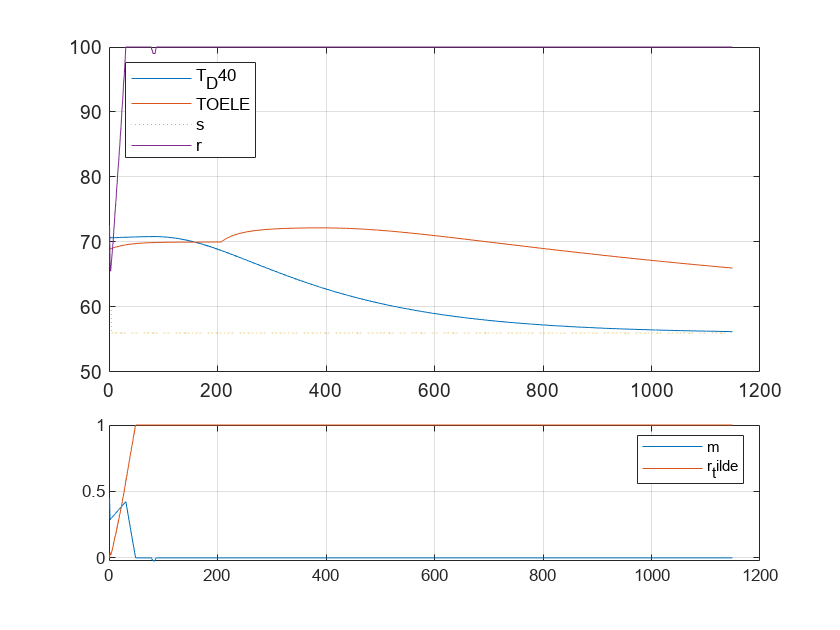

clear
eins = [1; 2; 3; 4];
zwei = 2 * eins;
drei = 3 * eins;
t = table(eins, zwei, drei);
writetable(t, 'tabellentest.txt');

while true
    try
        p = readtable("Raspberry pi git\ABB_pi\Monitor/log.txt");
    catch exception
    end
    l = size(p); l=l(1);
    start = max(1,l-10000);
    p = p(start:end,:);
    
    subplot(3,1,[1 2])
    plot(p.T_D40)
    hold on
    plot(p.TOELE)
    grid on
    plot(p.s,':')
    plot(50 + p.r * 50)
    hold off
    legend({'T_D40', 'TOELE', 's', 'r'}, 'Location', 'northwest');
    
    subplot(3,1,3)
    plot(p.m)
    hold on
    plot(p.r_tilde)
    legend({'m','r_tilde'})
    %text(0.1,0.1,sprintf('s_V = %.2f', p.s_V(end)))
    grid on
    hold off
    drawnow

    pause(0.21)
end